## **Лабораторная работа №3**

### **Задание: по уравнению волны из учебника построить волну в одномерной/двумерной потенциальной яме.**

clc; clear;

a1 = 1e-9;
a2 = 1e-9;

Размеры потенциальной ямы

n1 = 1;
n2 = 1;

Стартовые энергетические уровни

points = 100;
x1 = linspace(0,a1,points);
x2 = linspace(0,a2,points);
[X1,X2] = meshgrid(x1,x2);

Задание стартовой сетки по размерам потенциальной ямы.

Разметка сеток соответстсвия для анимации.

z = zeros(100);
F = figure();
s = surf(X1,X2,z, 'EdgeColor', 'none');

z - заранее потготовленная матрица для посчитанных значений частицы в яме.

s - поверхность, значения Z-оси которой мы будем просчитывать в каждом шаге анимации.

while isvalid(F)
    n1 = n1 + 0.01; % Взял одну сотую для плавности анимации
    n2 = n2 + 0.01; % По-строгому, прибавлять должны по 1
    s.ZData = countZ(a1,a2,n1,n2,X1,X2);
    drawnow;
    pause(1/60); % Если прибавляем по 1, то и пауза должна быть сильно больше
end

Для недублирования кода функция просчёта значений приведена ниже. В ходе цикла просто подмениваем значения и обновляем картинку.

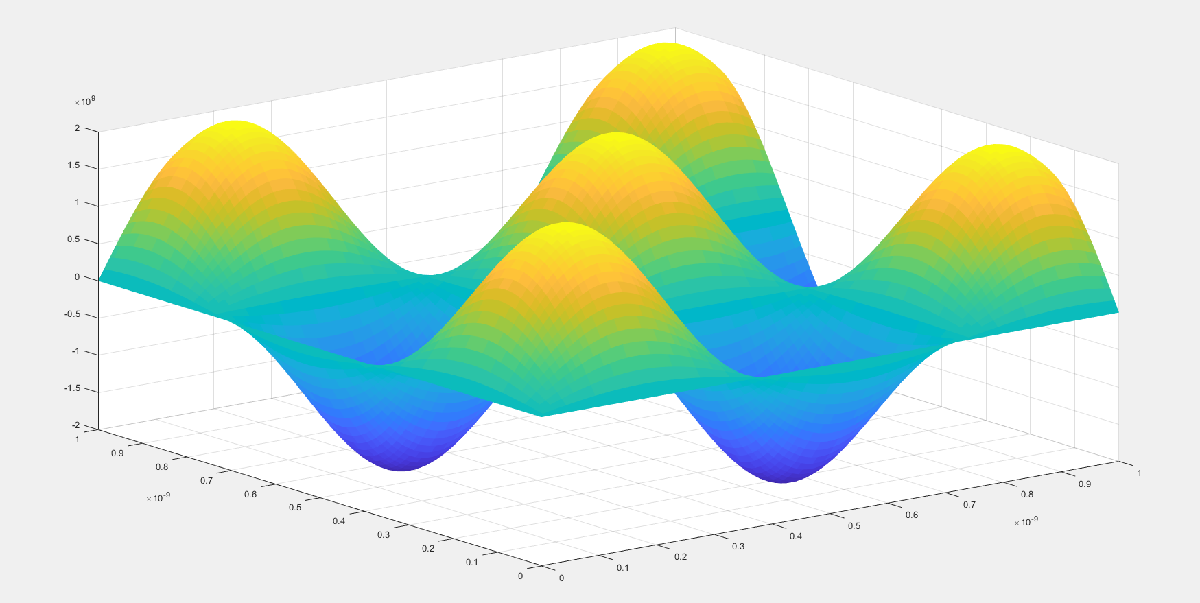

function z = countZ(a1,a2,n1,n2,X1,X2) 
    z = sqrt(4 / (a1 * a2)) * sin(pi * n1 * X1 / a1) .*  sin(pi * n2 * X2 / a2);
end

#### Вывод: по аналитическому уровнения из учебника получили зависимость частицы в 2D потенциальной яме. Построили данную зависимость на разных энергетических уровнях.